# 2023-2_MEN611_EX01

## Problema 4

4.1 y 4.2)

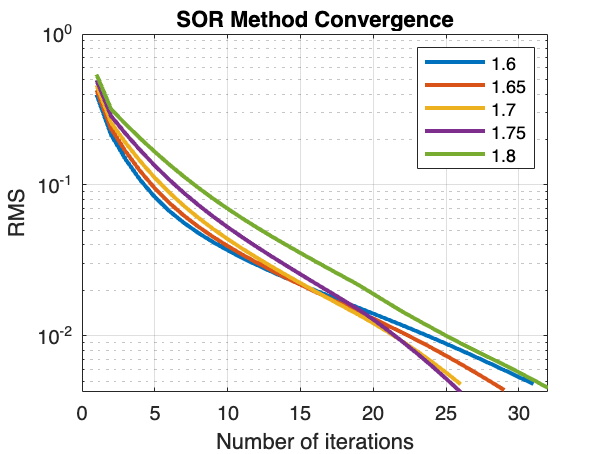

%Workspace clean up
clear all
close all
clc
%% Entries
L_x = 2.0;
L_y = 2.0;
w=[1.6, 1.65 ,1.7, 1.75, 1.8];
n_x = 21;
n_y = n_x;
tol =5e-3;

clear RMS
clear it
for i_w = 1:length(w)
    d_x = L_x/(n_x-1);
    d_y = L_y/(n_y-1);
    T_n = zeros(n_x,n_y);
    T = T_n;
    
    [n_X,n_Y] = meshgrid(1:1:n_x,1:1:n_x);
    RMSS = 10e6;
    % condiciones de contorno
    for i = 1:n_x
        T(i,end) = 2;
        T(i,1) = sin(pi()*(i-1)*d_x/L_x);
    end

    for j = 1:n_y
        T(1,j) = (j-1)*d_y;
        T(end,j) = (1/4)*(((j-1)*d_y)^3);
    end
    T_n = T;

    % Iterative process - SOR
    cont = 1;
    while (RMSS>tol)
        for i = 2:n_x-1
            for j = 2:n_y-1
                T_n(i,j) = ((1-w(i_w))*T(i,j))+(w(i_w)/4)*(T(i+1,j)+T_n(i-1,j)+T(i,j+1)+T_n(i,j-1));
            end
        end
        RMSS = sqrt(sum(sum((T_n-T).^2))/(n_x*n_y));
        T = T_n;
        RMS(cont,i_w) = RMSS;
        it(cont,i_w) = cont;
        cont=cont+1;
    end
end
figure
p1 = semilogy(it,RMS);
grid on
title('SOR Method Convergence')
xlabel('Number of iterations')
ylabel('RMS')
legend({'1.6' '1.65' '1.7' '1.75'  '1.8'})
set(p1, 'LineWidth',2)

4.3 y 4.4)

%Workspace clean up
clear all
close all
clc
%% Entries
L_x = 2.0;
L_y = 2.0;
w=[1.75];
n_x = 21;
n_y = n_x;
tol =5e-3;

clear RMS
clear it
for i_w = 1:length(w)
    d_x = L_x/(n_x-1);
    d_y = L_y/(n_y-1);
    T_n = zeros(n_x,n_y);
    T = T_n;
    
    [n_X,n_Y] = meshgrid(1:1:n_x,1:1:n_x);
    RMSS = 10e6;
    % condiciones de contorno
    for i = 1:n_x
        T(i,end) = 2;
        T(i,1) = sin(pi()*(i-1)*d_x/L_x);
    end

    for j = 1:n_y
        T(1,j) = (j-1)*d_y;
        T(end,j) = (1/4)*(((j-1)*d_y)^3);
    end
    T_n = T;

    % Iterative process - SOR
    cont = 1;
    while (RMSS>tol)
        for i = 2:n_x-1
            for j = 2:n_y-1
                T_n(i,j) = ((1-w(i_w))*T(i,j))+(w(i_w)/4)*(T(i+1,j)+T_n(i-1,j)+T(i,j+1)+T_n(i,j-1));
            end
        end
        RMSS = sqrt(sum(sum((T_n-T).^2))/(n_x*n_y));
        T = T_n;
        RMS(cont,i_w) = RMSS;
        it(cont,i_w) = cont;
        cont=cont+1;
    end
end
Tmid=T((n_x+1)/2,(n_y+1)/2);
sprintf('La temperatura en el centro geométrico de la placa analizada es T = %d', Tmid)

ans = 'La temperatura en el centro geométrico de la placa analizada es T = 1.045512e+00'

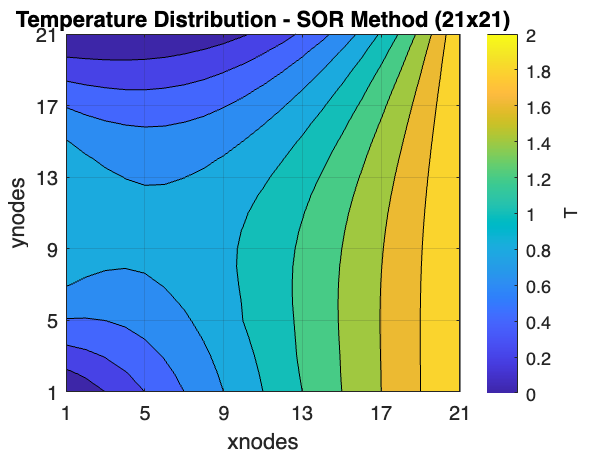

figure
contourf(T)
c = colorbar;
%c.Ticks(-0.14:0.02:0);
c.Label.String = 'T';
axis([1 n_x 1 n_y])
xticks(1:((n_x-1)/5):n_x)
yticks(1:((n_y-1)/5):n_y)
xlabel('xnodes')
ylabel('ynodes')
title(['Temperature Distribution - SOR Method (',num2str(n_x),'x',num2str(n_y),')'])
grid on 